Fundamentos de control                                                                                                                                                                                                       

# Descripción externa e interna

## Descripción externa de sistemas

Tradicionalmente, el trabajo de los ingenieros de control comienza con el desarrollo de un **modelo matemático** de la planta/proceso/sistema dinámico a controlar: un conjunto de ecuaciones que representan la dinámica del sistema con precisión. Estas ecuaciones, independientemente de la naturaleza del sistema, se describen en términos de **ecuaciones diferenciales** obtenidas a partir de **leyes fisicas** que gobiernan dicho sistema (p.ej. leyes de Kirchhoff para sistemas eléctricos o de Newton para sistemas mecánicos), y nos permiten conocer y entender como se comporta nuestro sistema. 

La **teoría de control clásica**, centrada en sistemas SISO (Single Input Single Output) invariantes en el tiempo, propone la representación del modelo matemático como **función de transferencia**. Esta es especialmente útil para analizar la respuesat transitoria o la respuesta en frecuencia de este tipo de sistemas, como veremos más adelante.

## 1. Funciones de transferencia

La función de transferencia $G\left(s\right)$ que caracteriza a un sistema se construye a partir de las ecuaciones diferencias que lo modelan, y está definida como la relación entre la **transformada de Laplace **de la salida $Y\left(s\right)$ y la transformada de la entrada $U\left(s\right)$, con condiciones iniciales (CI) nulas:


$$\textrm{Función}\;\textrm{de}\;\textrm{transferencia}=G\left(s\right)=\frac{L\left\lbrace \left(y\left(t\right)\right)\right\rbrace }{L\left\lbrace x\left(t\right)\right\rbrace }=\frac{Y\left(s\right)}{X\left(S\right)}{\left|\right.}_{\textrm{CI}=0}$$


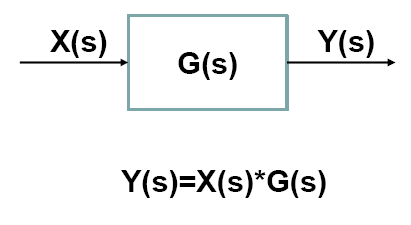 

De este modo, para el sistema lineal e invariante en el tiempo (LTI) $a_0 y^{\left.n\right)} +a_1 y^{n-1} +\cdots +a_{n-1} y^{\prime } +a_n y=b_0 x^{\left.m\right)} +b_1 x^{\left.m-1\right)} +\cdots +b_{m-1} x^{\prime } +b_m x$ con $n\ge m$ (sistema causal), se tiene que:


$$G\left(s\right)=\frac{Y\left(s\right)}{X\left(s\right)}=\frac{b_0 s^m +b_1 s^{m-1} +\cdots +b_{m-1} s+b_m }{a_0 s^n +a_1 s^{n-1} +\cdots +a_{n-1} s+a_n }$$


donde:

- $n$ (potencia más alta del denominador, también llamado **ecuación característica**) es el **orden** del sistema.

- Las raíces del denominador son los **polos** del sistema.

- Las raíces del numerador son los **ceros** del sistema.

Dicho de otro modo, la función de transferencia permite representar nuestro sistema,originalmente expresado en el dominio del tiempo en forma de ecuaciones diferenciales cuya manipulación puede ser compleja, por medio de una nueva variable compleja $s$ en forma de ecuaciones algebráicas, empleando para ello la transformada de Laplace. 

A esta representación se la conoce como **descripción externa **del sistema, ya que no acarrea ninguna información sobre la estructura interna o estructura física del mismo.

**Tarea 1:** Dada la siguiente función de transferencia $G\left(s\right)=\frac{s^2 +2s+1}{s^3 +4s+1}$, obten sus ceros y sus polos. ¿Cuál es el orden del sistema?

*Pista: Recuerda el cuaderno sobre polinomios y el comando *`roots`*.*

% Tu código aquí
num = [1 2 1];
den = [1 0 4 1];
%obtenemos los polos 
polos = roots(den)

polos =    0.1231 + 2.0113i
   0.1231 - 2.0113i
  -0.2463 + 0.0000i


%obtenemos los ceros 
ceros = roots(num)

ceros =     -1
    -1


`Resultado esperado:`

## 2. Creación de modelos de sistemas con formato de funciones de transferencia. 

MATLAB nos brinda la **Control System Toolbox**, un conjunto de herramientas para trabajar con modelos lineales de sistemas y su control. La construcción de una función de transferencia de un sistema se puede abordar por tres caminos diferentes, con la función tf, el comando zpk,o de forma directa. Veamos cada una de ellas.

### 2.1 tf

La primera manera de definir funciones de transferencia es mediante el comando `tf`. Su sintaxis es:

- `Sys = tf( num, den )`: donde `num` y `den` son, respectivamente, los vectores de coeficientes de los polinomios del numerador y denominador de la función de transferencia. 

Tras la ejecución de esta función, la función de transferencia se muestra en pantalla como un cociente de polinomios en s no factorizados (a partir de ahora a este formato se le denominará formato tf).

Ejemplo: 

Dado un sistema cuya función de transferencia es:


$$G\left(s\right)=\frac{2s+2}{s^2 +3s+5}$$


Su modelo es utilizable por MATLAB mediante una variable `G` creada tal que así:

num = [2 2]; % Numerador: 2s + 2
den = [1 3 5]; % Denominador s^2 + 3s + 5
G = tf(num,den)

G =
 
     2 s + 2
  -------------
  s^2 + 3 s + 5
 
Continuous-time transfer function.
Model Properties


**Tarea 2:** Sea el sistema definido por $G\left(s\right)=\frac{14s+140}{s^3 +9s^2 +33s+65}$, obtener su función de transferencia en MATLAB usando el comando `tf`.

% Tu código aquí
num = [14 140];
den = [1 9 33 65];
G = tf(num,den)

G =
 
        14 s + 140
  -----------------------
  s^3 + 9 s^2 + 33 s + 65
 
Continuous-time transfer function.
Model Properties


`Resultado esperado:`

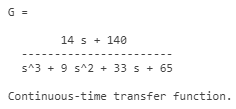

**Tarea 3:** Sea el sistema definido por $G\left(s\right)=\frac{14\left(s+10\right)}{\left(s+5\right)\left(s+2-3i\right)\left(s+2+3i\right)}$, obtener su función de transferencia en MATLAB usando el comando `tf`. Comprueba que el resultado coincide con la función de transferencia de la Tarea 2.

*Pista: Aquí el comand ****conv**** puede ser útil.*

% Tu código aquí
 num = 14*[1 10]

num =     14   140


 u = [1 5];
 v = [1 2-3i];
 g = [1 2+3i];
 den = conv(conv(u,v),g)

den =      1     9    33    65


G = tf(num,den)

G =
 
        14 s + 140
  -----------------------
  s^3 + 9 s^2 + 33 s + 65
 
Continuous-time transfer function.
Model Properties


### 2.2 zpk

El segundo método de definición de funciones de transferencia es mediante el comando `zpk`. Su sintaxis es:

- `Sys = zpk( ceros, polos, k ):` donde `ceros` y `polos` son, respectivamente, vectores que contienen a todos los ceros y polos de la función de transferencia y `k` es el valor de la ganancia homónima, en el caso en el que la función de transferencia se exprese en la forma:


$$\textrm{Sys}\left(s\right)=\frac{k\prod_{j=1}^{j=m} \left(s-{\textrm{cero}}_j \right)}{\prod_{i=1}^{i=n} \left(s-{\textrm{polo}}_i \right)}$$


Si la función de transferencia considerada no tiene polos o ceros, el correspondiente vector deberá especificarse como vacío: `[ ]`. Tras la ejecución de esta función, la función de transferencia se muestra en pantalla como un cociente de polinomios en s factorizados (a partir de ahora a este formato se le denominará formato zpk). 

Ejemplo: 

Dado un sistema cuya función de transferencia es:


$$G\left(s\right)=\frac{2\left(s+2\right)}{\left(s+3\right)\left(s+5\right)}$$


Su modelo es utilizable por MATLAB mediante una variable G creada así: 

z = -2;
p = [-3 -5];
k = 2;
G = zpk(z,p,k)

G =
 
    2 (s+2)
  -----------
  (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


% O directamente
G = zpk( -2, [ -3 -5 ], 2 )

G =
 
    2 (s+2)
  -----------
  (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


**Tarea 4:** Sea el sistema definido por $G\left(s\right)=\frac{14\left(s+10\right)}{\left(s+5\right)\left(s+2-3i\right)\left(s+2+3i\right)}$, obtener su función de transferencia en MATLAB usando el comando `zpk`. 

% Tu código aquí
z = -10;
p = [-5 -2+3i -2-3i];
k = 14;
G = zpk(z,p,k)

G =
 
        14 (s+10)
  ---------------------
  (s+5) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


`Resultado esperado:`

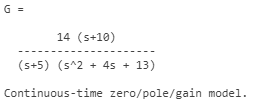

**Tarea 5:** Sea el sistema definido por $G\left(s\right)=\frac{14s+140}{s^3 +9s^2 +33s+65}$, obtener su función de transferencia en MATLAB usando el comando `zpk`. El resultado ha de ser el mismo que en la Tarea 4.

*Pista: Aquí *`roots`* puede ser útil de nuevo.*

% Tu código aquí
num = [14 140];
den = [1 9 33 65];
z = roots(num)

z = -10

p = roots(den)

p =   -5.0000 + 0.0000i
  -2.0000 + 3.0000i
  -2.0000 - 3.0000i


G = zpk(z,p,14)

G =
 
        14 (s+10)
  ---------------------
  (s+5) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


### 2.3 De forma directa

Si la función de transferencia considerada tiene polos y/o ceros, el valor de la función de transferencia podrá asignarse directamente, como un cociente de polinomios expresado en su formato algebraico ordinario y cuya variable independiente se denomina $s$, si con anterioridad se ejecuta una cualquiera de las dos siguientes instrucciones: 

- `s = tf('s')`

- `s = zpk('s')`

La única diferencia que se observaría tras la ejecución de una de estas dos funciones está en el formato con que MATLAB mostraría las funciones de transferencia que fueran creadas a continuación. Si se opta por la primera opción, se mostrarían con formato `tf` y si se opta por la segunda, se mostrarían con formato `zpk`.

Ejemplo 1: 

Dado un sistema cuya función de transferencia es: 


$$G\left(s\right)=\frac{2s+2}{s^2 +3s+5}$$


Su modelo es utilizable por MATLAB mediante una variable G creada así:

s = tf('s'); 
G = (2*s+2)/(s^2+3*s+5)

G =
 
     2 s + 2
  -------------
  s^2 + 3 s + 5
 
Continuous-time transfer function.
Model Properties


Ejemplo 2: 

Dado un sistema cuya función de transferencia es:


$$G\left(s\right)=\frac{2\left(s+2\right)}{\left(s+3\right)\left(s+5\right)}$$


Su modelo es utilizable por MATLAB mediante una variable G creada así:

s = zpk('s');
G = 2*(s+2)/((s+3)*(s+5))

G =
 
    2 (s+2)
  -----------
  (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


% Incluso aunque lo introduzcamos con "formato" tf
G = (2*s+4)/(s^2+8*s+15)

G =
 
    2 (s+2)
  -----------
  (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


**¡OJO! **Nótese que en función de la forma en la que venga expresada la función de transferencia, puede ser más interesante definirla usando el comando `tf`, `zpk`, o de forma directa.

**Tarea 6:** Sea el sistema definido por $G\left(s\right)=\frac{14s+140}{s^3 +9s^2 +33s+65}$, obtener su función de transferencia en MATLAB de forma directa, esto es, sin emplear los comandos `tf` ni `zpk`, de tal manera que el sistema resultante esté expresado en formato `zpk`. Comprobar que el resultado es el mismo que en la Tarea 5.

% Tu código aquí
s = zpk('s');
num = roots([14 140])

num = -10

den = roots([1 9 33 65])

den =   -5.0000 + 0.0000i
  -2.0000 + 3.0000i
  -2.0000 - 3.0000i


G = 14*(s+10)/((s+5)*(s+2-3i)*(s+2+3i))

G =
 
        14 (s+10)
  ---------------------
  (s+5) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


## 3. Modificación del formato de presentación de funciones de transferencia

Una vez que una función de transferencia esté definida en el espacio de trabajo de MATLAB, se puede modificar el formato con el que ésta se muestra en su ventana de comandos: 

- Si se desea pasar de formato zpk a formato tf, se ha de hacer: 

- Si se desea pasar de formato tf a formato zpk, se ha de hacer:

**Tarea 7:** Convierte la función de transferencia en formato `zpk` de la Tarea 5 a formato `tf `y almacenalo en una nueva variable `G2`. Tras esto, convierte `G2` de nuevo a formato `zpk`. El resultado ha de ser el mismo que el obtenido en la Tarea 6.

% Tu código aquí

G2 = tf (G)

G2 =
 
        14 s + 140
  -----------------------
  s^3 + 9 s^2 + 33 s + 65
 
Continuous-time transfer function.
Model Properties


G2 = zpk(G2)

G2 =
 
        14 (s+10)
  ---------------------
  (s+5) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


## 4. Representación del diagrama de polos y ceros de un sistema (pzmap). 

Una vez que una variable contiene el modelo de un sistema, es posible generar una representación gráfica en la que se muestre la ubicación en el plano complejo de los polos y ceros del referido modelo. Dicha representación gráfica se denomina diagrama de polos y ceros del sistema. La función de MATLAB que permite obtener el diagrama de polos y ceros de un sistema a partir de su modelo es `pzmap`. Esta función es utilizable de forma independiente del formato en que esté expresado el modelo del sistema en cuestión (`tf` o `zpk`). 

Para obtener el diagrama de polos y ceros de un sistema cuyo modelo está almacenado en una variable denominada `Sys`, se ha de hacer: 

El diagrama obtenido se muestra en una ventana independiente de la ventana principal del paquete MATLAB. Los polos son representados en dicho diagrama empleando un aspa (‘x’) y los ceros son representados mediante una circunferencia (‘o’).

Ejemplo:

Dibujemos los polos y los ceros de la función:


$$H\left(s\right)=\frac{2\left(s+2\right)}{\left(s+3\right)\left(s+5\right)}$$


s = zpk('s');
H = 2*(s+2)/((s+3)*(s+5))

H =
 
    2 (s+2)
  -----------
  (s+3) (s+5)
 
Continuous-time zero/pole/gain model.
Model Properties


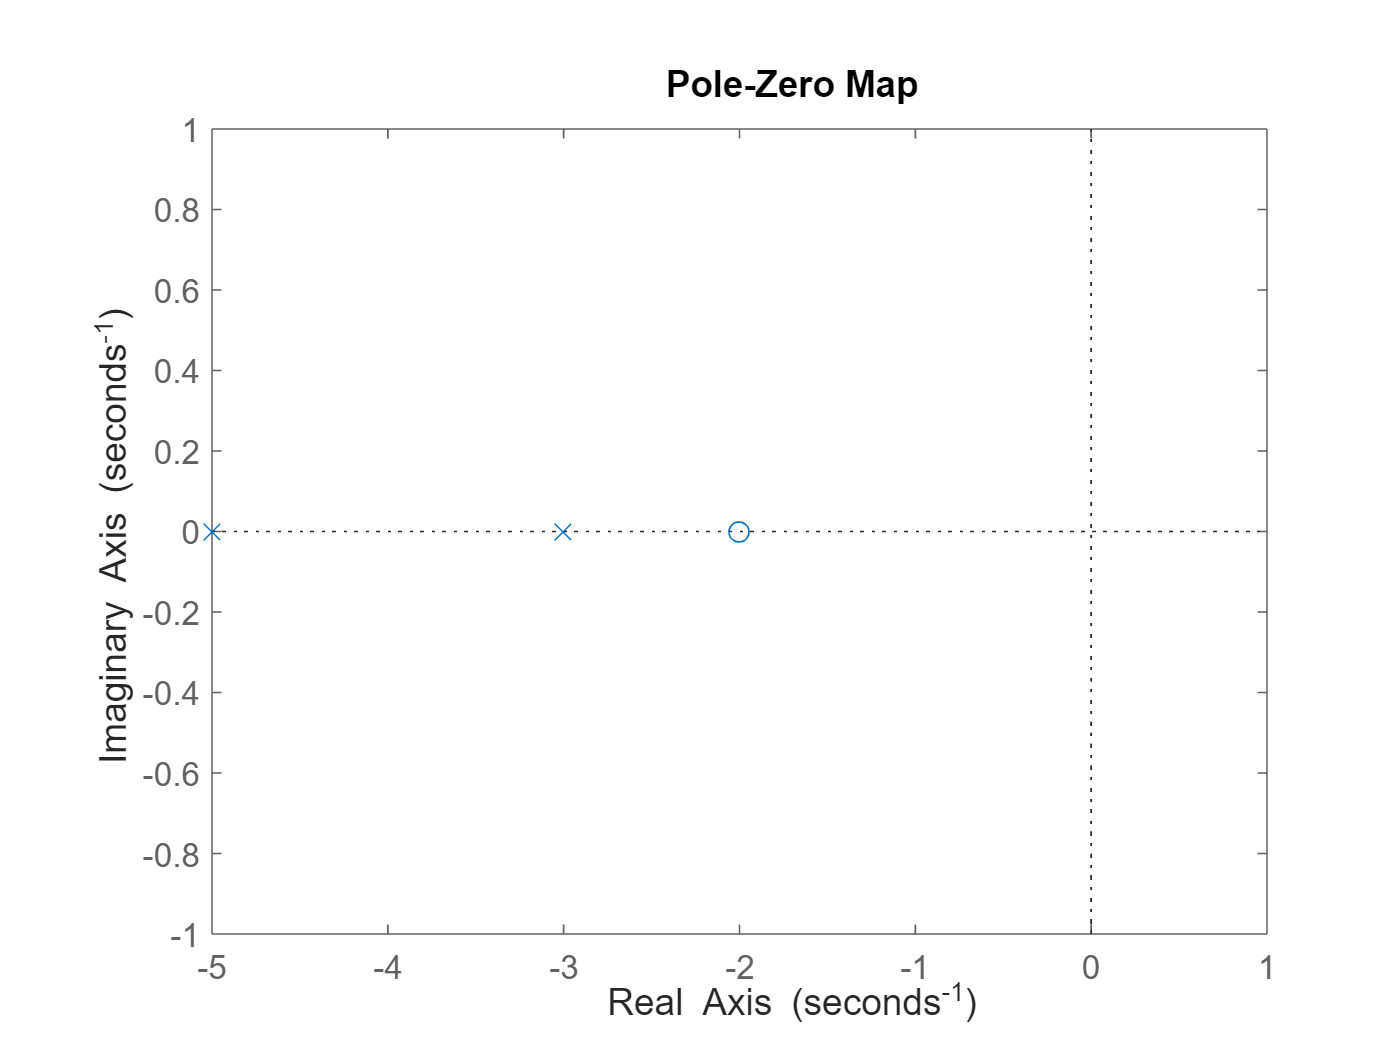

pzmap(H)

**Tarea 8:** Obtén la representación de zeros y polos del sistema empleado en la Tarea 7.

% Tu código aquí
s = zpk('s')

s =
 
  s
 
Continuous-time zero/pole/gain model.
Model Properties


G2

G2 =
 
        14 (s+10)
  ---------------------
  (s+5) (s^2 + 4s + 13)
 
Continuous-time zero/pole/gain model.
Model Properties


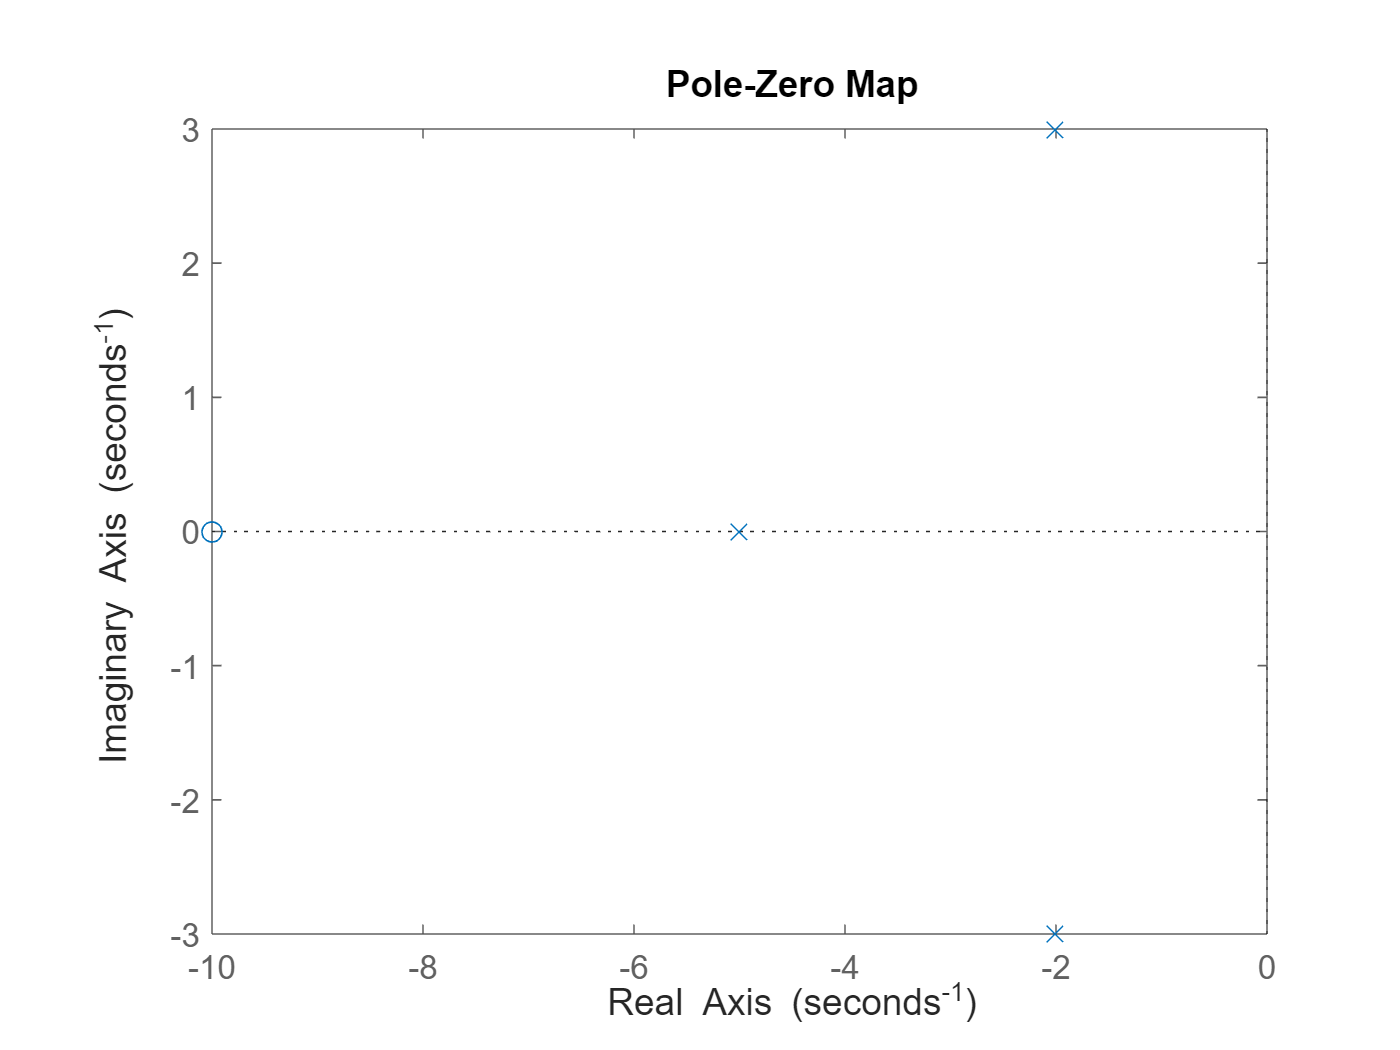

pzmap(G2)

`Resultado esperado:`

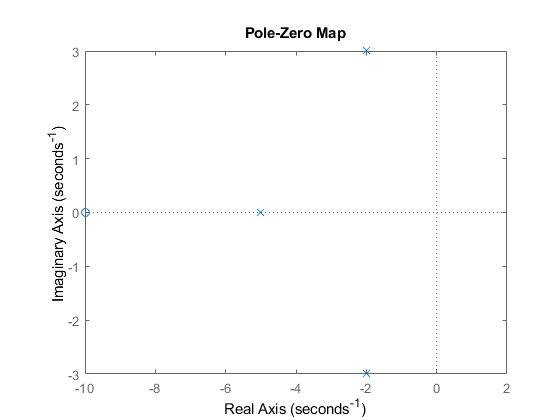

## 5. Acceso a los datos de un modelo de sistema (tfdata, zpkdata). 

Una vez que una variable contiene el modelo de un sistema, es posible acceder a los correspondientes datos del mismo. Independientemente del formato empleado en la creación de dicho modelo, es posible acceder a los datos característicos que el mismo tendría en caso de ser expresado con un formato diferente. 

- Si se desea conocer, con formato `tf`, los datos de un modelo de un sistema almacenado en una variable denominada `Sys`, se ha de hacer:` [num, den] = tfdata(Sys,'v').` Ejemplo:

% La v indica que la salida sean vectores en vez de celdas
[num,den] = tfdata(H,'v')                       

num =          0    2.0000    4.0000


den =     1.0000    8.0000   15.0000


- Si se desea conocer, con formato `zpk`, los datos de un modelo de un sistema almacenado en una variable denominada `Sys`, se ha de hacer:` [z,p,k] = zpkdata(Sys,'v')`. Ejemplo:

[z,p,k]=zpkdata(G,'v')

z = -10.0000

p =   -5.0000 + 0.0000i
  -2.0000 + 3.0000i
  -2.0000 - 3.0000i


k = 14

- Si se desea conocer sólo los ceros de un modelo de un sistema almacenado en una variable denominada `Sys`, se ha de hacer: `z = zero(Sys)`. Ejemplo:

z = zero(H)

z = -2.0000

z = zero(G)

z = -10.0000

- Si se desea conocer sólo los polos de un modelo de un sistema almacenado en una variable denominada `Sys`, se ha de hacer:` p = pole(Sys)`. Ejemplo:

p = pole(H)

p =    -3.0000
   -5.0000


**Tarea 9:** De un sistema se conoce que su modelo ha sido asignado a una variable H así:

H = tf([2 2],[1 3 5])

H =
 
     2 s + 2
  -------------
  s^2 + 3 s + 5
 
Continuous-time transfer function.
Model Properties


Obtener, con formato `tf`, los datos del modelo del sistema.

*Pista:** ¡Recuerda la famosa 'v'!*

% Tu código aquí
[num,den] = tfdata(H,'v')

num =      0     2     2


den =      1     3     5


`Resultado esperado:`

**Tarea 10**: Obtener, con formato zpk, los datos del modelo del sistema.

% Tu código aquí
[z,p,k]=zpkdata(H,'v')

z = -1

p =   -1.5000 + 1.6583i
  -1.5000 - 1.6583i


k = 2

`Resultado esperado:`

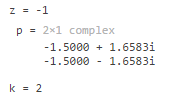

**Tarea 11:** Obtener sólo los ceros del modelo del sistema:

% Tu código aquí
z = zero(H)

z = -1

`Resultado esperado: `

**Tarea 12:** Obtener sólo los polos del modelo del sistema.

% Tu código aquí

z = pole(H)

z =   -1.5000 + 1.6583i
  -1.5000 - 1.6583i


`Resultado esperado:`